% % getting whole group workflow (up til now) together

% add path to functions/scripts
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\KC_thresh_functions

% load individual vars into group cell arrays
[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupIdxSmallPupilTrials, groupIdxLargePupilTrials, groupLongAxis, groupMeanPupilDiameterAllTrials, groupRunThresh, groupPupThresh] = makeGroupStruct();
% of no pup data:
%[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupRunThresh] = makeGroupStruct_noPup();

% get stim conditions in order of trial & list of stim params to loop thru
% (This needs to be done new w/in the loop too each sess since the order of trialCond matters.. right now it's jsut to define cont & durat etc)
n = 1;
[durOrderedByTrialMeetCriteria,uniqueDurations,conOrderedByTrialMeetCriteria,uniqueContrasts,conAndDurOrderedByTrialMeetCriteria] = getStimParams4loops(n,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);

% in preparation for making pixel wise figures of fluorescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
reigons
cons4Legend
durs4Legend 

% CRFs

% which areas/stimulus parameters to loop over:

n = 1; % this is just to get the number of points
visArea = 1:length(groupRoundXpts{1,n})
%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

%durat = 1:length(uniqueDurations)
durat = 1 % (durat = 1 means 100 ms in final set of expts)

cont = 1:length(uniqueContrasts)
%cont = 7;

% LOCO NO PUP

% stat group CRF matrix
state = 'loRun'
clear loRun_allSessAllPtsAllDurs_CRF
[loRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% duration x contrasts x points x sessions
sizeloRunAllSessAllPtsAllDurs_CRF = size(loRun_allSessAllPtsAllDurs_CRF)

% run group CRF matrix
state = 'hiRun'
clear hiRun_allSessAllPtsAllDurs_CRF
[hiRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiRunAllSessAllPtsAllDurs_CRF = size(hiRun_allSessAllPtsAllDurs_CRF)


% for crf figs
yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];
x_axis = [1:length(uniqueContrasts)];
xMax = max(x_axis);
xMin = min(x_axis);
xLimit = [xMin xMax];

% PLOT locomotion CRF
stateLegend = {'stat','run'}
plotCompareBehState_CRF(loRun_allSessAllPtsAllDurs_CRF,hiRun_allSessAllPtsAllDurs_CRF,durat,yMax,yMin,yLimit,x_axis,xMax,xMin,xLimit,stateLegend,uniqueContrasts,reigons,nGroup);

% for mean Trace figs

visArea = 1;
%visArea = 4;

%visArea = 1:length(groupRoundXpts{1,n})
durat = 1:length(uniqueDurations)
cont = 1:length(uniqueContrasts)

yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];

%x_axis = [1:length(uniqueContrasts)];
%xMax = max(x_axis);
%xMin = min(x_axis);
%xLimit = [xMin xMax];

% locomotion mean trace figs
stateLegend = {'stat','run'}
plotCompareBehState_mnTrace(loRun_mnTraceAllConsDursPts,hiRun_mnTraceAllConsDursPts,cons4axes,visArea,durat,cont,yMax,yMin,yLimit,stateLegend,nGroup)

% Mean Trace PUP
state = 'loPup'
[loPup_mnTraceAllConsDursPts] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeLoPup_mnTraceAllConsDursPts = size(loPup_mnTraceAllConsDursPts)

state = 'hiPup'
[hiPup_mnTraceAllConsDursPts] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeHiPup_mnTraceAllConsDursPts = size(hiPup_mnTraceAllConsDursPts)

% pupil mean trace figs
stateLegend = {'loPup','hiPup'}
plotCompareBehState_mnTrace(loPup_mnTraceAllConsDursPts,hiPup_mnTraceAllConsDursPts,cons4axes,visArea,durat,cont,yMax,yMin,yLimit,stateLegend,nGroup)

% HISTOs - # trials also in this code...

% SESSIOn VARS

%durat = 1:length(uniqueDurations);
durat = 1

cont = 1:length(uniqueContrasts)
%cont = 7

visArea = 1:length(groupRoundYpts{1})
%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

sess = 1:nGroup

state = 'loRun'

[loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeLoRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial)
% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}

state = 'hiRun'

[hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial)
% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}

% both PLOT

%durat = 1:length(uniqueDurations);
durat = 1

cont = 1:length(uniqueContrasts)
%cont = 7

visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3 % AL
%visArea = 4 % AM 
%visArea = 5 % control

sess = 1:nGroup
%sess = 1

yMax = 0.22;
yLimit = [0 yMax];

xMax = 0.225;
xMin = -0.1;
xLimit = [xMin xMax];

xTickRange = [xMin:0.05:xMax];
xTickLabelRange = [xMin:0.05:xMax];

edgeWidth = 0.01;
edges = [xMin xMin:edgeWidth:xMax xMax];
%numBins = 25;

fig2 = figure

fig2 =   Figure (19) with properties:

      Number: 19
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


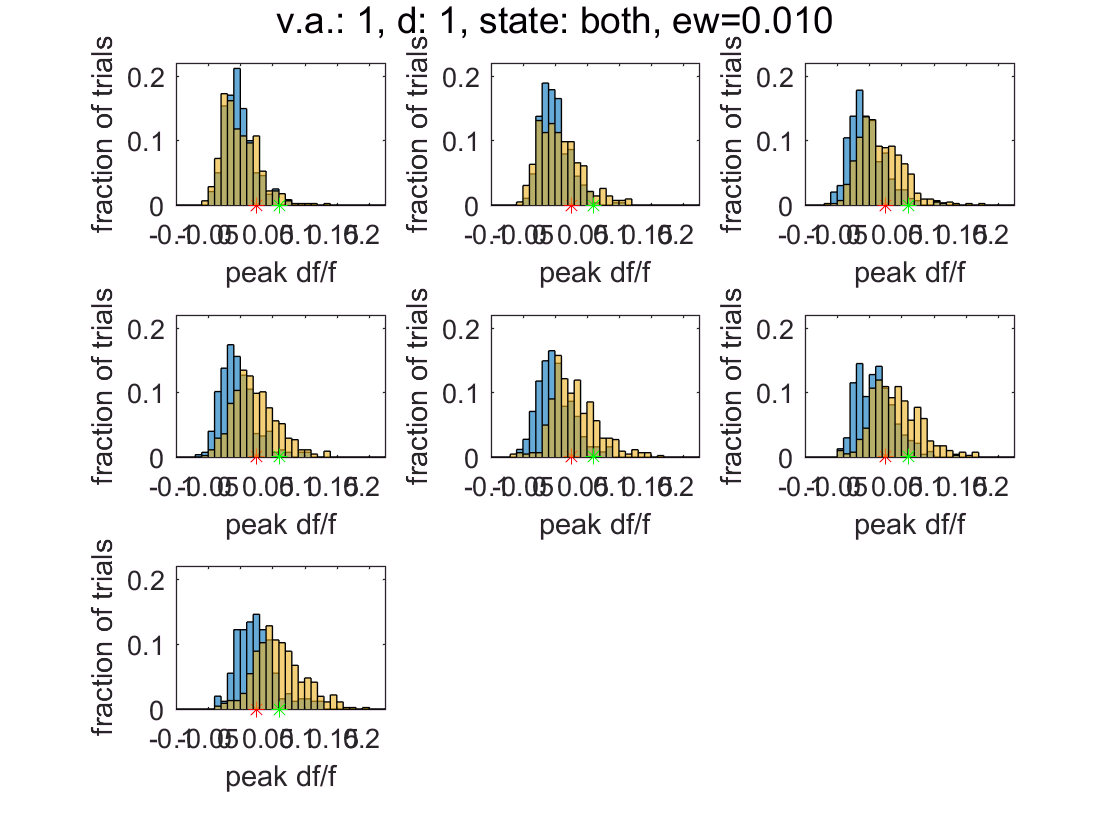


formatSpec = 'v.a.: %1.f, d: %1.f, state: %s, ew=%0.3f \n';
titleText = sprintf(formatSpec,visArea,durat,'both',edgeWidth);
suptitle(titleText)


clear d
for d = durat
    
    
    clear i
    for i = visArea % this code might only ever get run one visual area at a time? 
        % so no collecting # trials for each area and duration just yet... 
        % just save vars out named by area then re-run code for next area etc
      
        clear lo_numTrialsAllSess_AllCons
        clear lo_sumTrialsAcrossSess_AllCons 
        
        clear lo_mnDf_allCons
        clear hi_mnDf_allCons
        
        clear lo_stderr_allCons
        clear hi_stderr_allCons
        
            
        clear c
        for c = cont
            
            clear lo_dthithCthNth_pkDfEachTrial
            lo_dthithCthNth_pkDfEachTrial = []; 
        
            clear hi_dthithCthNth_pkDfEachTrial
            hi_dthithCthNth_pkDfEachTrial = [];
             
            
            clear n
            for n = sess
  
                % get values for 1st sesson, cth dth ith trials
                lo_dthithCthNth_pkDfEachTrial = [lo_dthithCthNth_pkDfEachTrial,loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                % for nth trial, cth contrast, save num of trials at this contrast
                % num trials this n this c
                lo_numTrialsAllSess_AllCons(n,c) = length(loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c});
                
                hi_dthithCthNth_pkDfEachTrial = [hi_dthithCthNth_pkDfEachTrial,hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                % for nth trial, cth contrast, save num of trials at this contrast
                hi_numTrialsAllSess_AllCons(n,c) = length(hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c});
                
            end % end n loop - now have all mean peak df values for each trial, all sessions pooled
            % but for only 1 con
            
            % COLLECT
            % for each sess, cth contrast, save num of trials at this contrast
            lo_sumTrialsAcrossSess_eachCon = sum(lo_numTrialsAllSess_AllCons(:,c));
            % COLLECTING
            lo_sumTrialsAcrossSess_AllCons(1,c) = lo_sumTrialsAcrossSess_eachCon;
    
            
            % PLOT LO STATE one con at a time, all sess at once, each subplot
            
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
            h1 = histogram(lo_dthithCthNth_pkDfEachTrial,edges,'Normalization','probability');
            
            % COLLECT
            lo_mnDf_eachCon = mean(lo_dthithCthNth_pkDfEachTrial);
            % COLLECTING
            lo_mnDf_allCons(1,c) = lo_mnDf_eachCon;
       
            y = 0;
        
            hold on
                
            % COLLECT
            lo_stderr_eachCon = (std(lo_dthithCthNth_pkDfEachTrial))/(sqrt(length(lo_sumTrialsEachCon_allSess)));
            % COLLECTING
            lo_stderr_allCons(1,c) = lo_stderr_eachCon;
            
            h2 = scatter(lo_mnDf_stat,y,'*','r');
            
            %formatSpec = 'c=%s, mn=%0.3f, st=%0.3f, n=%1.0f';
            %title(sprintf(formatSpec,cons4axes{c},mnDf,stdev,lo_sumNumTrialsEachCon_allSess));
            %title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            
            set(gca,'XTick',xTickRange)
            set(gca,'XTickLabel',xTickLabelRange)
            
            hold on
            
            % HI STATE PLOT
            
            % COLLECT
            % for all sess, cth contrast, save num of trials at this contrast
            %%hi_sumTrialsAcrossSess_eachCon = sum(hi_numTrialsOneSessOneC(:,c),1);
            % COLLECTING
            %%hi_sumTrialsAcrossSess_AllCons(1,c) = hi_sumTrialsAcrossSess_eachCon;
            
            % COLLECT
            % for each sess, cth contrast, save num of trials at this contrast
            hi_sumTrialsAcrossSess_eachCon = sum(hi_numTrialsAllSess_AllCons(:,c));
            % COLLECTING
            hi_sumTrialsAcrossSess_AllCons(1,c) = hi_sumTrialsAcrossSess_eachCon;
            
            
            
            
            % PLOT one con at a time, all sess at once, each subplot
            
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
            h3 = histogram(hi_dthithCthNth_pkDfEachTrial,edges,'Normalization','probability');
            
            % COLLECT
            hi_mnDf_eachCon = mean(hi_dthithCthNth_pkDfEachTrial);
            hi_mnDf_allCons(1,c) = hi_mnDf_eachCon;

            y = 0;
        
            hold on
                
            % COLLECT
            hi_stderr_eachCon = (std(hi_dthithCthNth_pkDfEachTrial))/(sqrt(hi_sumTrialsEachCon_allSess));
            hi_stderr_allCons(1,c) = hi_stderr_eachCon;
            
            h4 = scatter(mnDf_run,y,'*','g');
            
            formatSpec = 'c=%s, mnS=%0.3f, stS=%0.3f, \n mnR=%0.3f, stR=%0.3f nT=%1.0f,%1.0f';
            %title(sprintf(formatSpec,cons4axes{c},mnDf_stat,stdev_stat, mnDf_run,stdev_run,lo_sumTrialsEachCon_allSess,hi_sumTrialsEachCon_allSess));
            %title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            
            set(gca,'XTick',xTickRange)
            set(gca,'XTickLabel',xTickLabelRange)
            
            
        end % end c loop
        
    end % end i loop

end % end d loop


size(lo_numTrialsAllSess_AllCons)

ans =      3     7


size(hi_numTrialsAllSess_AllCons)

ans =      3     7



size(lo_sumTrialsAcrossSess_AllCons)

ans =      1     7


size(hi_sumTrialsAcrossSess_AllCons)

ans =      1     7


        
size(lo_mnDf_allCons)

ans =      1     7


size(hi_mnDf_allCons)

ans =      1     7


        
size(lo_stderr_allCons)

ans =      1     7


size(hi_stderr_allCons)

ans =      1     7


% STATS

% here we use the ouput 'loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial' 
% from function 'Histo_byBehState_noPup', which is also used in 'groupHisto.mlx'

% 2 sample t test on trial vectors (lo vs hi state)

% picking an alpha value (correct for mult. comparisons)
n_cons = 7 % # contrasts 

n_cons =      7


denom = n_cons-1 % # comparisons

denom =      6


alf = 0.05/denom % bonferroni correction for multiple comparisons

alf =        0.00833333333333333


% this code is similar to the histo code in that it gathers all trials across all sess for each con,
% but different in that
% it then performs a 2 sample t test and saves out the test statistics
% also the histo function saves all the trials as nested cell array, which I don't need here

clear h_p_cil_cih__tstats_AllPairs
clear tstats_AllPairs

clear h_p_cil_cih__tstats_AllPairs_AllPts
clear tstats_AllPairs_AllPts

clear h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs
clear tstats_AllPairs_AllPts_AllDurs

%%figure

for d = 1
    
    for i = 1
        
        %for c = 1
        for c = 1:length(uniqueContrasts)
            
            % get df for each trial vector across all sessions, one
            % contrast at a time
            
            clear lo_dthithCthNth_pkDfEachTrial
            lo_dthithCthNth_pkDfEachTrial = []; 
        
            clear hi_dthithCthNth_pkDfEachTrial
            hi_dthithCthNth_pkDfEachTrial = [];
                
            clear n
            for n = sess
  
                % get values for 1st sesson, cth dth ith trials
                lo_dthithCthNth_pkDfEachTrial = [lo_dthithCthNth_pkDfEachTrial,loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                
                hi_dthithCthNth_pkDfEachTrial = [hi_dthithCthNth_pkDfEachTrial,hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                
            end % end n loop - now have all mean peak df values for each trial, all sessions pooled
            % but for only 1 con

            %%subplot(2,4,c)
            
            % one con at a time at first
            %%cdfplot(hi_dthithCthNth_pkDfEachTrial)
            
            %%hold on
            
            %%cdfplot(lo_dthithCthNth_pkDfEachTrial)
            
            [h,p,ci,t_stats] = ttest2(lo_dthithCthNth_pkDfEachTrial,hi_dthithCthNth_pkDfEachTrial,'Alpha',alf);
            
            %%title(sprintf('c=%1.0f, va=%1.0f, h=%1.0f, p=%0.4f',c,i,h,p))
            
            %%axis square
            
            h_p_cil_cih__tstats_AllPairs(1,c) = h; % c-1 so index doesn't start at 2
            h_p_cil_cih__tstats_AllPairs(2,c) = p;
            h_p_cil_cih__tstats_AllPairs(3,c) = ci(1,1);
            h_p_cil_cih__tstats_AllPairs(4,c) = ci(1,2);
            tstats_AllPairs{1,c} = t_stats;

            
        end % end contrast loop
        
        % collect stats x contrast grid for each point
        h_p_cil_cih__tstats_AllPairs_AllPts(:,:,i) = h_p_cil_cih__tstats_AllPairs;
        tstats_AllPairs_AllPts{i,:} = tstats_AllPairs;
        
    end % end i loop
    
    h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs(:,:,:,d) = h_p_cil_cih__tstats_AllPairs_AllPts;
    tstats_AllPairs_AllPts_AllDurs{d,:} = tstats_AllPairs_AllPts
    
end % end d loop

tstats_AllPairs_AllPts_AllDurs =     {1x1 cell}



% stats param x comparison contrast x points
size(h_p_cil_cih__tstats_AllPairs_AllPts_AllDurs)

ans =      4     7


size(tstats_AllPairs_AllPts_AllDurs)

ans =      1     1


% plot sig stars on crf based on ttest results



% do ks test

% plot h, p, and vert lines on cdf plot